**Ex 3.1.1 a)**

T = [0.7, 0.8; 0.3, 0.2];

X_nFaltar = [1; 0];

T2 = T^2;

matriz_res = (T2 * X_nFaltar);
prob = matriz_res(1)

prob = 0.7300

**Ex 3.1.1 b)**

T = [0.7, 0.8; 0.3, 0.2];

X_Faltar = [0; 1];

T2 = T^2;

matriz_res = (T2 * X_Faltar);
prob = matriz_res(1)

prob = 0.7200

**Ex 3.1.1 c)**

T = [0.7,0.8 ; 0.3,0.2];
X_nfaltar = [1 ; 0]; 
T29 = T^(2*15-1);

res_matriz = (T29*X_nfaltar);
prob = res_matriz(1)

prob = 0.7273

**Ex 3.1.1 d)**

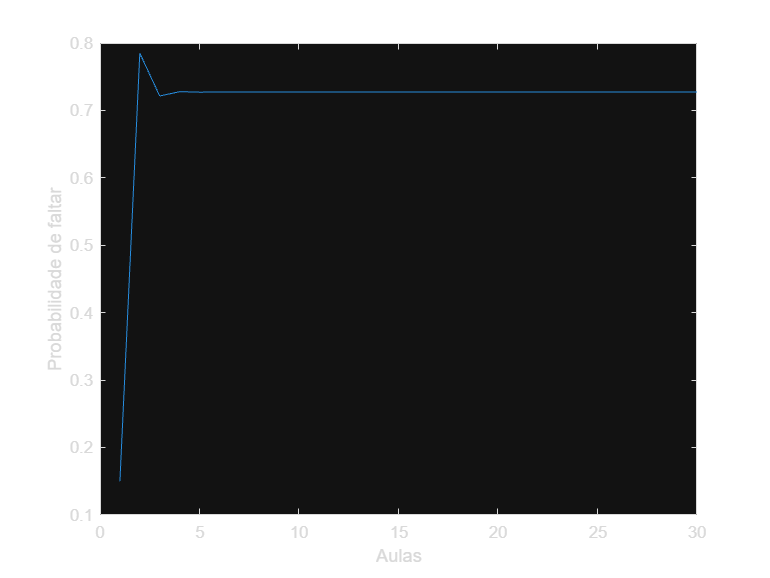

T = [0.7 0.8 ; 0.3 0.2];

prob = zeros(1,30);
  
X_faltar = [0.15 ; 0.85]; 

for aula = 1 : 30
    matriz = T^(aula-1) * X_faltar;
    prob(aula) = matriz(1);
end
  
plot(1:30,prob);
xlabel("Aulas");
ylabel("Probabilidade de faltar");  

**Ex 3.1.2 a)**

T = [1/3 1/4 0 ; 1/3 11/20 1/2 ; 1/3 1/5 1/2]

T =     0.3333    0.2500         0
    0.3333    0.5500    0.5000
    0.3333    0.2000    0.5000



disp("É estocástica pois não temos entradas negativas e a soma de cada coluna dá sempre 1");

É estocástica pois não temos entradas negativas e a soma de cada coluna dá sempre 1


**Ex 3.1.2 b)**

x0 = [60/90, 15/90, 15/90];

**Ex 3.1.2 c)**

T = [1/3 1/4 0 ; 1/3 11/20 1/2 ; 1/3 1/5 1/2];
x0 = [60/90 ; 15/90 ; 15/90];

x30 = T^30*x0;
alunos = 90.*x30

alunos =    16.6667
   44.4444
   28.8889


**Ex 3.1.2 d)**

T = [1/3 1/4 0 ; 1/3 11/20 1/2 ; 1/3 1/5 1/2];
x0 = [30/90 ; 30/90 ; 30/90];

x30 = T^30*x0;
alunos = 90*x30

alunos =    16.6667
   44.4444
   28.8889


**Ex 3.1.3 a)**

T = zeros(20,20);

for k = 1 : 20
  r = rand(20, 1);
  r = r / sum(r);
  
  T(:,k) = r;
end 

disp(T);

    0.0898    0.0361    0.1072    0.0849    0.0148    0.0304    0.0141    0.0809    0.0908    0.0852    0.0956    0.0589    0.0468    0.0498    0.0619    0.0763    0.0847    0.0322    0.0125    0.0663
    0.0810    0.0152    0.0627    0.0430    0.0203    0.0101    0.0174    0.0403    0.0429    0.0480    0.0554    0.0536    0.0380    0.0917    0.0354    0.0226    0.0207    0.0085    0.0059    0.0890
    0.0131    0.0163    0.0303    0.0962    0.1030    0.0370    0.0763    0.0322    0.0423    0.0704    0.0407    0.0128    0.0305    0.0407    0.0813    0.0110    0.0094    0.0589    0.1091    0.0533
    0.0630    0.0883    0.0143    0.0464    0.0319    0.0221    0.0400    0.0380    0.0029    0.0501    0.0957    0.0545    0.0615    0.0051    0.0473    0.1071    0.0695    0.0353    0.0470    0.0456
    0.0037    0.0935    0.0171    0.0508    0.0255    0.0640    0.0162    0.0721    0.0506    0.0143    0.0266    0.0147    0.0372    0.0321    0.1076    0.0651    0.0039    0.0828    0.0097    0.

disp("É estocástica pois não temos entradas negativas e a soma de cada coluna dá sempre 1");

É estocástica pois não temos entradas negativas e a soma de cada coluna dá sempre 1


**Ex 3.1.3 b)**

T = zeros(20,20);

for k = 1 : 20
  r = rand(20, 1);
  r = r / sum(r);
  
  T(:,k) = r;
end 

x0 = zeros(1,20)';
x0(1) = 1;

x2 = (T^2)*x0;
res2 = x2(20)*100

res2 = 5.3469


x5 = (T^5)*x0;
res5 = x5(20)*100

res5 = 4.9311


x10 = (T^10)*x0;
res10 = x10(20)*100

res10 = 4.9302


x100 = (T^100)*x0;
res100 = x100(20)*100

res100 = 4.9302

**Ex 3.1.4 a)**

p = 0.4;
q = 0.6;

AtoA = p^2;
AtoB = (1-p)^2;
AtoC = p*(1-p);
AtoD = p*(1-p);

BtoA = 0;
BtoB = 0;
BtoC = 0;
BtoD = 1;

CtoA = 0;
CtoB = 0;
CtoC = 0;
CtoD = 1;

DtoA = q^2;
DtoB = q*(1-q);
DtoC = q*(1-q);
DtoD = (1-q)^2;

T = [AtoA BtoA CtoA DtoA ; AtoB BtoB CtoB DtoB ; AtoC BtoC CtoC DtoC ; AtoD BtoD CtoD DtoD]

T =     0.1600         0         0    0.3600
    0.3600         0         0    0.2400
    0.2400         0         0    0.2400
    0.2400    1.0000    1.0000    0.1600


**Ex 3.1.4 b)**

p = 0.4;
q = 0.6;

AtoA = p^2;
AtoB = (1-p)^2;
AtoC = p*(1-p);
AtoD = p*(1-p);

BtoA = 0;
BtoB = 0;
BtoC = 0;
BtoD = 1;

CtoA = 0;
CtoB = 0;
CtoC = 0;
CtoD = 1;

DtoA = q^2;
DtoB = q*(1-q);
DtoC = q*(1-q);
DtoD = (1-q)^2;

T = [AtoA BtoA CtoA DtoA ; AtoB BtoB CtoB DtoB ; AtoC BtoC CtoC DtoC ; AtoD BtoD CtoD DtoD];
x0 = [1 ; 0 ; 0 ; 0];

x5 = (T^5)*x0;
x10 = (T^10)*x0;
x100 = (T^100)*x0;
x200 = (T^200)*x0;

probA_5 = x5(1)

probA_5 = 0.2103

probB_5 = x5(2)

probB_5 = 0.1824

probC_5 = x5(3)

probC_5 = 0.1624

probD_5 = x5(4)

probD_5 = 0.4448


probA_10 = x10(1)

probA_10 = 0.1979

probB_10 = x10(2)

probB_10 = 0.1821

probC_10 = x10(3)

probC_10 = 0.1583

probD_10 = x10(4)

probD_10 = 0.4616


probA_100 = x100(1)

probA_100 = 0.1979

probB_100 = x100(2)

probB_100 = 0.1821

probC_100 = x100(3)

probC_100 = 0.1583

probD_100 = x100(4)

probD_100 = 0.4617


probA_200 = x200(1)

probA_200 = 0.1979

probB_200 = x200(2)

probB_200 = 0.1821

probC_200 = x200(3)

probC_200 = 0.1583

probD_200 = x200(4)

probD_200 = 0.4617

**Ex 3.1.4 c)**

**Ex 3.1.5 a)**

T = [0.7 0.2 0.3 ; 0.2 0.3 0.3 ; 0.1 0.5 0.4]

T =     0.7000    0.2000    0.3000
    0.2000    0.3000    0.3000
    0.1000    0.5000    0.4000


**Ex 3.1.5 b)**

T = [0.7 0.2 0.3 ; 0.2 0.3 0.3 ; 0.1 0.5 0.4];

Sol1 = 1;
Sol2 = Sol1 * T(1,1);
Sol3 = Sol2 * T(1,1)

Sol3 = 0.4900

**Ex 3.1.5 c)**

T = [0.7 0.2 0.3 ; 0.2 0.3 0.3 ; 0.1 0.5 0.4]

T =     0.7000    0.2000    0.3000
    0.2000    0.3000    0.3000
    0.1000    0.5000    0.4000


sol = 1;
nuvens = 2;
chuva = 3;

p_c = T(sol, sol) * T(sol, sol) + T(sol, sol) * T(sol, nuvens) + T(sol, nuvens) * T(nuvens, sol) + T(sol, nuvens) * T(nuvens, nuvens)

p_c = 0.7300

**Ex 3.1.5 d)**

T = [0.7 0.2 0.3 ; 0.2 0.3 0.3 ; 0.1 0.5 0.4];

v = [1 ; 0 ; 0];

diaSol = 1;
diaNuvens = 0;
diaChuva = 0;

for i = 2:31
    v = T*v;
    diaSol = diaSol + v(1);
    diaNuvens = diaNuvens + v(2);
    diaChuva = diaChuva + v(3);
end

fprintf("Numero médio de dias de sol: %f\n", diaSol);

Numero médio de dias de sol: 15.148808


fprintf("Numero médio de dias de nuvens: %f\n", diaNuvens);

Numero médio de dias de nuvens: 7.530882


fprintf("Numero médio de dias de chuva: %f\n", diaChuva); 

Numero médio de dias de chuva: 8.320310


**Ex 3.1.5 e)**

T = [0.7 0.2 0.3 ; 0.2 0.3 0.3 ; 0.1 0.5 0.4];

x0 = [0 ; 0 ; 1];

diaSol = 0;
diaNuvens = 0;
diaChuva = 1;

for i = 2:31
    x0 = T*x0;
    diaSol = diaSol + x0(1);
    diaNuvens = diaNuvens + x0(2);
    diaChuva = diaChuva + x0(3);
end

fprintf("Numero médio de dias de sol: %f\n", diaSol);

Numero médio de dias de sol: 13.453893


fprintf("Numero médio de dias de nuvens: %f\n", diaNuvens);

Numero médio de dias de nuvens: 7.700373


fprintf("Numero médio de dias de chuva: %f\n", diaChuva);

Numero médio de dias de chuva: 9.845734


**Ex 3.1.5 f)**

T = [0.7 0.2 0.3 ; 0.2 0.3 0.3 ; 0.1 0.5 0.4];

dores = 0.1;

x0 = [1 ; 0 ; 0];

for i = 2:31
    x0 = T*x0;
    dores = dores + 0.1*x0(1) + 0.3*x0(2) + 0.5*x0(3);
end

fprintf("Numero médio de dores com 1ºsol: %f\n", dores);

Numero médio de dores com 1ºsol: 7.934300




dores = 0.5;

x0 = [0 ; 0 ; 1];

for i = 2:31
    x0 = T*x0;
    dores = dores + 0.1*x0(1) + 0.3*x0(2) + 0.5*x0(3);
end

fprintf("Numero médio de dores com 1ºchuva: %f\n", dores);

Numero médio de dores com 1ºchuva: 8.578368


**Ex 3.1.6 a)**

T = [0.8 0 0 0.3 0 ; 0.2 0.6 0 0.2 0 ; 0 0.3 1 0 0 ; 0 0.1 0 0.4 0 ; 0 0 0 0.1 1]

T =     0.8000         0         0    0.3000         0
    0.2000    0.6000         0    0.2000         0
         0    0.3000    1.0000         0         0
         0    0.1000         0    0.4000         0
         0         0         0    0.1000    1.0000


**Ex 3.1.6 b)**

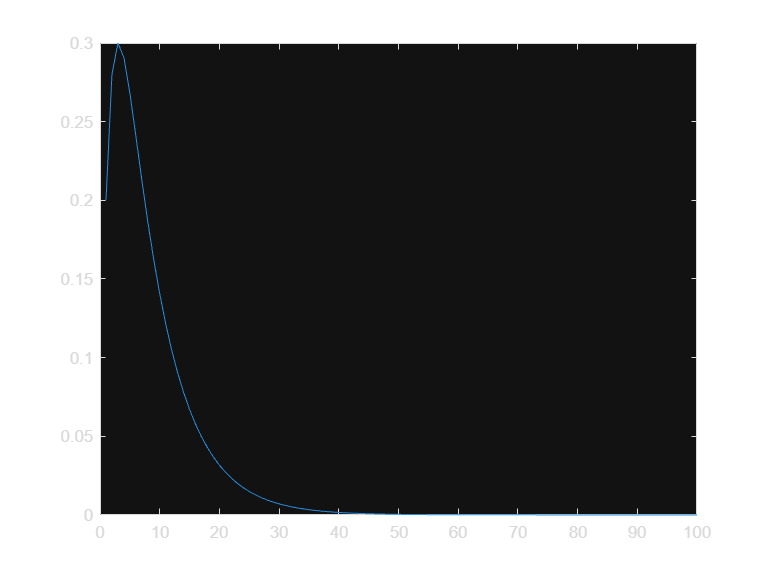

T = [0.8 0 0 0.3 0 ; 0.2 0.6 0 0.2 0 ; 0 0.3 1 0 0 ; 0 0.1 0 0.4 0 ; 0 0 0 0.1 1];
x0 = [1 ; 0 ; 0 ; 0 ; 0];

n = 1:100;
estado2 = zeros(1,100);

for i =1:100
    v = T^i*x0;
    estado2(i) = v(2);
end

plot(n, estado2);

**Ex 3.1.6 c)**

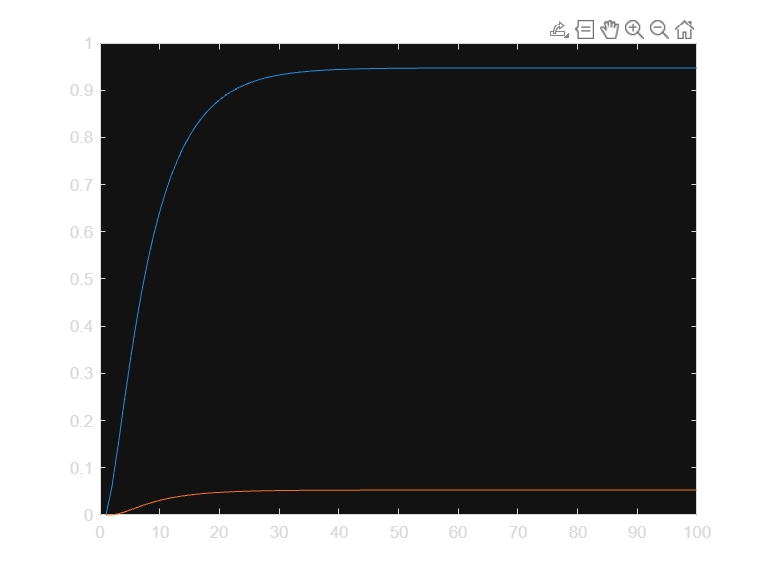

T = [0.8 0 0 0.3 0 ; 0.2 0.6 0 0.2 0 ; 0 0.3 1 0 0 ; 0 0.1 0 0.4 0 ; 0 0 0 0.1 1];
x0 = [1; 0; 0; 0; 0];

n = 1:100;
estado3 = zeros(1,100);
estado5 = zeros(1,100);

for i = 1:100
    v = T^i*x0;
    estado3(i) = v(3);
    estado5(i) = v(5);
end

plot(n, estado3, n, estado5);

**Ex 3.1.6 d)**

Tcan = [0.8 0 0.3 0 0 ; 0.2 0.6 0.2 0 0 ; 0 0.1 0.4 0 0 ; 0 0.3 0 1 0 ; 0 0 0.1 0 1];

Q = Tcan(1:3,1:3)

**Ex 3.1.6 e)**

Tcan = [0.8 0 0.3 0 0 ; 0.2 0.6 0.2 0 0 ; 0 0.1 0.4 0 0 ; 0 0.3 0 1 0 ; 0 0 0.1 0 1];

Q = Tcan(1:3,1:3);

F = inv(eye(length(Q))-Q)

**Ex 3.1.6 f)**

Tcan = [0.8 0 0.3 0 0 ; 0.2 0.6 0.2 0 0 ; 0 0.1 0.4 0 0 ; 0 0.3 0 1 0 ; 0 0 0.1 0 1];

Q = Tcan(1:3,1:3);

F = inv(eye(length(Q))-Q);

E = sum(F);
fprintf("Nº passos a começar em 1: %f\n", E(1));
fprintf("Nº passos a começar em 2: %f\n", E(2));
fprintf("Nº passos a começar em 4: %f\n", E(3));

**Ex 3.1.6 g)**

Tcan = [0.8 0 0.3 0 0 ; 0.2 0.6 0.2 0 0 ; 0 0.1 0.4 0 0 ; 0 0.3 0 1 0 ; 0 0 0.1 0 1];

Q = Tcan(1:3,1:3);
R = Tcan(4:5,1:3);
F = inv(eye(length(Q))-Q);

B = R*F;

fprintf("Começando no estado 1, prob. absorção do estado 3: %f\n", B(1,1));
fprintf("Começando no estado 1, prob. absorção do estado 5: %f\n", B(2,1));

**Ex 3.1.7 a)**

H = [0 0 0 0 1/3 0 ; 1 0 0 0 1/3 0 ; 0 1/2 0 1 0 0 ; 0 0 1 0 0 0 ;  0 1/2 0 0 0 0 ; 0 0 0 0 1/3 0];
r = (ones(1,6)/6)';

for i = 1:10
    r = H*r;
end

r

**Ex 3.1.7 c)**

H = [0 0 0 0 1/3 1/6 ; 1 0 0 0 1/3 1/6 ; 0 1/2 0 1 0 1/6 ; 0 0 1 0 0 1/6 ; 0 1/2 0 0 0 1/6 ; 0 0 0 0 1/3 1/6];
r = (ones(1,6)/6)';

for i = 1:10
    r = H*r;
end

r

**Ex 3.1.7 d)**

H = [0 0 0 0 1/3 1/6 ; 1 0 0 0 1/3 1/6 ; 0 1/2 0 1 0 1/6 ; 0 0 1 0 0 1/6 ; 0 1/2 0 0 0 1/6 ; 0 0 0 0 1/3 1/6];

beta = 0.8;
A = beta*H + (1-beta)*ones(length(H),length(H))/6;
r = (ones(1,6)/6)';

for i = 1:10
    r = A*r;
end

r

**Ex 3.1.7 e)**

H = [0 0 0 0 1/3 1/6 ; 1 0 0 0 1/3 1/6 ; 0 1/2 0 1 0 1/6 ; 0 0 1 0 0 1/6 ; 0 1/2 0 0 0 1/6 ; 0 0 0 0 1/3 1/6];

beta = 0.8;
A = beta*H + (1-beta)*ones(length(H),length(H))/6;
r = (ones(1,6)/6)';

epsilon = 1e-4;
iter = 0
while 1
    iter = iter +1;
    rold = r;
    r = A*r;
    if max(abs(r-rold))<epsilon
        break;
    end
end

iter